# Backtester3AndRebal

dbstop if error

## Load data

load /Users/crystal/Desktop/BackendBenchmarking/New_Engine+OppRebal3+Brinson/Nov_11_update_V1/Database/positions.mat
load /Users/crystal/Desktop/BackendBenchmarking/New_Engine+OppRebal3+Brinson/Nov_11_update_V1/Database/clients.mat
load /Users/crystal/Desktop/BackendBenchmarking/New_Engine+OppRebal3+Brinson/Nov_11_update_V1/Database/performance.mat
load /Users/crystal/Desktop/BackendBenchmarking/New_Engine+OppRebal3+Brinson/Nov_11_update_V1/Database/timeseries_num.mat
load /Users/crystal/Desktop/BackendBenchmarking/New_Engine+OppRebal3+Brinson/Nov_11_update_V1/Database/tDict.mat
load /Users/crystal/Desktop/BackendBenchmarking/New_Engine+OppRebal3+Brinson/Nov_11_update_V1/Database/PortPriority.mat                               
load /Users/crystal/Desktop/BackendBenchmarking/New_Engine+OppRebal3+Brinson/Nov_11_update_V1/Database/MSDictionary.mat 
load /Users/crystal/Desktop/BackendBenchmarking/New_Engine+OppRebal3+Brinson/Nov_12_update_V2/Database/classify.mat                           
load /Users/crystal/Desktop/BackendBenchmarking/New_Engine+OppRebal3+Brinson/Nov_12_update_V2/Database/rebalancing_structure.mat 



load ..\Database\positions.mat                      % BACKEND BENCHMARK POSITION FILES

Error using load
Unable to read file '..\Database\positions.mat'. No such file or directory.

load ..\Database\clients.mat                        % BACKEND BENCHMARK TRADE FILES
load ..\Database\performance.mat                    % BACKEND BENCHMARK PERFORMANCE FILES
load ..\Database\timeseries_num.mat                 % NUMERICAL TIME SERIES (RETURNS) TABLE
load ..\Database\tDict.mat                          % TIME SERIES DICTIONARY TABLE FOR LOOKUPS
load ..\Database\PortPriority.mat                   % PORTFOLIO KEY TO MATCH PORTFOLIO CODES WITH NAMES
load ..\Database\MSDictionary.mat                   % MORNINGSTAR CATEGORIES AND BENCMARKS
load ..\Database\classify.mat                       % OTHER CATEGORIES AND BENCHMARKS
load ..\Database\rebalancing_structure.mat          % REBALANCING DATES FOR EACH PORTFOLIO

## Supplement MSDictionary

What symbols are missing from the Morningstar dictionary

missingSymbols = setdiff(tPsn.("Security Symbol"),tMSDict.ticker);
[symbolsInTClass, iTClass] = intersect(tClass.Symbol,missingSymbols);
tClass = tClass(iTClass,:);

Identify asset classes if a fund is invested in one class with more than 85% of its assets

cs = {'FUND_ASSET_ALLOC_GOVT','FUND_ASSET_ALLOC_MUNI','FUND_ASSET_ALLOC_CORP', ...
    'FUND_ASSET_ALLOC_EQUITY','FUND_ASSET_ALLOC_MTGE','FUND_ASSET_ALLOC_CASH_OTHER', ...
    'FUND_ASSET_ALLOC_PFD'};
[i,j]=find(double(tClass{:,cs})>85); % IF MORE THAN 85% OF THE FUND IS IN AN ASSET CLASS, CLASSIFY IT
tClass.AClass(i) = categorical(strrep(cs(j).','FUND_ASSET_ALLOC_',''));

Classify by sector

i = ~isundefined(tClass.RUSSELL_SECTOR_NAME);
tClass.Class(i) = tClass.RUSSELL_SECTOR_NAME(i);

Classify by HB_INDUSTRY_FOCUS

iE = find(tClass.AClass=={'EQUITY'} & isundefined(tClass.Class));
j = tClass.HB_INDUSTRY_FOCUS(iE);
i = ~isundefined(j);
tClass.Class(iE(i)) = categorical(cellstr(j(i)));

Classify by HB_GEOGRAPHIC_FOCUS

iE = find(tClass.AClass=={'EQUITY'} & isundefined(tClass.Class));
j = tClass.HB_GEOGRAPHIC_FOCUS(iE);
i = ~isundefined(j) & j~={'U.S.'};
tClass.Class(iE(i)) = categorical(cellstr(j(i)));

Classify by Market Cap

iE = find(tClass.Class=={'EQUITY'});
MC = tClass.HB_MARKET_CAP_FOCUS(iE);
i = ~isundefined(MC);
tClass.Class(iE(i)) = categorical(strcat(cellstr(tClass.Class(iE(i))),'|',cellstr(MC(i))));

HB_INDUSTRY_FOCUS HB_RATING_CLASS_FOCUS

i = isundefined(tClass.Class) & ...
    ~isundefined(tClass.AClass) & ...
    tClass.AClass~={'EQUITY'};
tClass.Class(i) = categorical(strcat(cellstr(tClass.HB_INDUSTRY_FOCUS(i)),'|', ...
    cellstr(tClass.HB_RATING_CLASS_FOCUS(i))));

Merge with Morningstar

H1 = height(tMSDict);
H2 = height(tClass);
tMSDict.ticker(      H1+1:H1+H2) = tClass.Symbol;

tMSDict.categoryName(H1+1:H1+H2) = tClass.Class;

Add ASSETID

j = isundefined(tMSDict.ASSETID)

j = 559×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


t = {'Technology'            ,'XLK US Equity'; ... % Technology Select Sector SPDR
     'Utilities'             ,'XLU US Equity'; ... % Utilities Select Sector SPDR
     'Consumer Discretionary','XLY US Equity'; ... % Consumer Discretionary Select Sector SPDR
     'Consumer Staples'      ,'XLU US Equity'; ... % Consumer Staples Select Sector SPDR
     'Energy'                ,'XLE US Equity'; ... % Energy Select Sector SPDR Fund
     'Financial Services'    ,'XLF US Equity'; ... % Financial Select Sector SPDR
     'Health Care'           ,'XLV US Equity'; ... % Health Care Select Sector SPDR
     'Materials & Processing','XLB US Equity'; ... % Materials Select Sector SPDR
     'Producer Durables'     ,'XLI US Equity'; ... %Industrial Select Sector SPDR
     'Communications'        ,'XLC US Equity'};    %Communication Services Select SPDR
s = regexprep(cellstr(tMSDict.categoryName(j)),strcat('^',t(:,1),'$'),t(:,2));
tMSDict.ASSETID(j) = categorical(strrep(s,'<undefined>',''));


## Backtest Parameters

rRF                = 0.1;                                       % THE RISK-FREE RATE (TO EARN ON CASH)
TransactionCosts = [0.02 0.05];                                 % [buy, sell] rate. Default to [0]
InitialWeights = [];                                            % InitialWeights for assets. Default to 0

% Inputs related to management and performance fee
ManagementFeeRate = 0; %0.05;                                       % Annual Rate. Default to 0

IncentiveFeeRate = 0; %0.2;                                         % Annual Rate. Default to 0
HighWatermark = 1;                                              % Boolean value 1 or 0, whether using highwatermark or not. Default to 0 (No high water mark is used)

HurdleFeeRate = 0;                                              % Annual Rate. Default to 0
Hurdle = 0;                                                     % Hurdle Boolean value 1 or 0, whether using Hurdle or not. 
                                                                % Default to 0 (No hurdle is used)
HurdleCompTable = [];                                           % Compare performance with HurdleCompTable. 
                                                                % Pay performance fee only if the return is higher than corresponded items in HurdleCompTable.
FID = fopen('storeManyBacktests.log','a');
fprintf(FID,'----------------------Begining storeManyBacktests.mlx %s]\n',datestr(now));
fclose(FID);

## Run

uPortCode = cellstr(unique(tPsn.("Portfolio Code")));           % PORTFOLIO CODES

uPortCode1 = uPortCode;

uPortCode= {'schk106'};     %schkc58 


Loop through all portfolios

NOTE: USE PARFOR INSTEAD OF FOR FOR CLOUD, DISTRIBUTED, OR PARALLEL PROCESSING

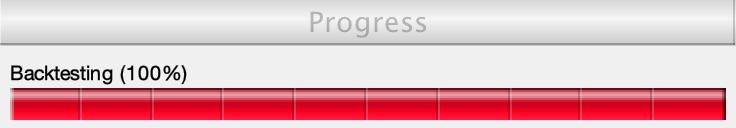

iResult = 0;
clear result 
tResultKey = [];
for iPort = 1:length(uPortCode)
    multiWaitbar( 'Backtesting', iPort./length(uPortCode));      % PROGRESS BAR

            Asset Allocation Dates

    tAA = buildTAA(uPortCode{iPort}, tPsn);                        % CREATE ASSET ALLOCATION TABLE
    tAADates = tAA.Time;
    tAA.Properties.VariableNames = lower(tAA.Properties.VariableNames);

##         Create Backtest Strategies

    cs = {'none','band','bench','tol'};
    costAnalyzerFcn = @(deltaMktVal) costAnalyzer(deltaMktVal);     % THIS FUNCTION CALCULATES TRANSACTION COSTS
    strats = [];
    
    rebalancingStep = 1;
    lookbackstep =1;
    
    RebalanceDate = nextbusinessdate(tAADates); % REBALANCE EVERY DAY
    ManagementFeeDate = [];%datemnth(min(tAADates),[0:12:1000]).'; % MGT FEE EVERY YEAR
    %IncentiveFeeDate = datemnth(min(tAADates),[0:1000]).'; % INCENTIVE FEE EVERY MONTH
    %ManagementFeeDate(ManagementFeeDate>max(tAADates)) = [];
    %IncentiveFeeDate(IncentiveFeeDate>max(tAADates)) = [];
    %ManagementFeeDate=nextbusinessdate(ManagementFeeDate);
    IncentiveFeeDate=[]; %nextbusinessdate(IncentiveFeeDate);
    HurdleFeeDate = [];                                             % Has to be a vector of business days, default to []
    for i=1:length(cs)                                              % LOOP THROUGH EACH STRATEGY
        strats = [strats backtestStrategy( ...
            cs{i}, ...                                              % STRATEGY NAME
            @(x, s, pwgt) rebalFn(x, s, pwgt,cs{i}),...             % REBALANCE FUNCTION HANDLE
            'LookbackWindow', lookbackstep,...                      % PASS THIS MANY ROWS OF DATA TO THE STRATEGY
            'RebalanceDate', RebalanceDate, ...
            'LookbackWindow', lookbackstep,...
            "ManagementFeeRate", ManagementFeeRate,...
            "IncentiveFeeRate", IncentiveFeeRate,...
            "Hurdle", Hurdle,...
            "HurdleFeeRate", HurdleFeeRate,...
            "ManagementFeeDate", ManagementFeeDate,...
            "IncentiveFeeDate", IncentiveFeeDate,...
            "HighWatermark", HighWatermark, ...
            "TransactionCosts", costAnalyzerFcn)];                   % THIS FUNCTION CALCULATES TRANSACTION COSTS
    end

            MorningStar benchmark strategy

            %'RebalanceFrequency', rebalancingStep, ...              % REBALANCE AFTER THIS MANY ROWS

Operator '==' is not supported for operands of type 'cell'.

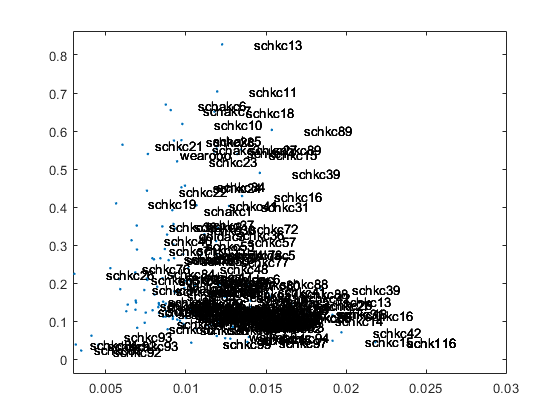

    stratsMS = backtestStrategy( ...
       'benchmark', ...                                              % STRATEGY NAME
        @(x, s, pwgt) rebalFn(x, s, pwgt, 'none'),...                % REBALANCE FUNCTION HANDLE
            'LookbackWindow', lookbackstep,...                      % PASS THIS MANY ROWS OF DATA TO THE STRATEGY
            'RebalanceDate', RebalanceDate, ...
            'LookbackWindow', lookbackstep,...
            "ManagementFeeRate", ManagementFeeRate,...
            "IncentiveFeeRate", IncentiveFeeRate,...
            "Hurdle", Hurdle,...

            "HurdleFeeRate", HurdleFeeRate,...
            "ManagementFeeDate", ManagementFeeDate,...
            "IncentiveFeeDate", IncentiveFeeDate,...
            "HighWatermark", HighWatermark, ...
            "TransactionCosts", costAnalyzerFcn);                   % THIS FUNCTION CALCULATES TRANSACTION COSTS

            Loop through portfolio then benchmark

    for iIsMSBench = 0:1                                          

                   Get input data

        if iIsMSBench                                               % FOR BENCHMARKs
            [tAA,oldVN,ASSET_ID] = buildBenchmarkTAA(tAA,tMSDict);  %    BUILD TAA AND ASSET_ID
        else                                                        % FOR PORTFOLIOS
            tAA = buildTAA(uPortCode{iPort}, tPsn);                 %    CREATE ASSET ALLOCATION TABLE
            tDict(tDict.("Security Symbol")=={'cash'},:) = [];      %    ERASE "CASH" FROM THE DICTIONARY
            ASSET_ID = buildIDTable(tDict,tAA);                     %    BUILD A DICTINARY OF ID
        end                                                       

                 Buld Prices Table

        tDAR = buildTDAR(tTSN, ASSET_ID);                            % CREAT A DAILY ASSET RETURN TABLE
        if ~isempty(tDAR)                                          
            tDAP = DAR2DAP(tDAR, min(tAA.Time));                     % CREATE A DAILY ASSET PRICE TABLE
            [tAA, tDAP] = alignTables(tAA, tDAP);                    % ALIGN TALBES
            if iIsMSBench                                            % For Benchmarks
                tDAP = fillInDupCols(tDAP);                          %    Fill in prices for duplicate columns
                tAA.Properties.VariableNames  = oldVN;               %    Change Morningstar coluimn names back to symbols
                tDAP.Properties.VariableNames = oldVN;                
            end                                                       

                       Add overdraft and cash columns if missing

           if isempty(strmatch('cash',tAA.Properties.VariableNames))
               tDAP.cash = ret2price(repmat(0.0001,height(tDAP)-1,1));
               tAA.cash = zeros(size(tDAP.cash));
           end
           if isempty(strmatch('overdraft',tAA.Properties.VariableNames))
               tDAP.overdraft = ret2price(repmat(0,height(tDAP)-1,1));
               tAA.overdraft = zeros(size(tDAP.overdraft));
           end

                           Define Backtest object

            [nSample, nAssets] = size(tDAR.Variables);
            if iIsMSBench s=stratsMS; else s=strats; end
            backtester_ = backtestEngine(s,'RiskFreeRate', rRF); 

                           Loop through all date combinations

            csDateCombo = {'All Dates'};%, 'One Year'};
            for iDate = 1:length(csDateCombo)
                tResultKey = [tResultKey; ...                        % KEEP TRACK OF SCENARIOS
                    cell2table([uPortCode(iPort) csDateCombo(iDate)], ...
                    'VariableNames',{'Portfolio','DateCombo'})];        

                if iIsMSBench                                             
                    tResultKey{end,1} = strcat(tResultKey{iResult,1},'_MSBench');    
                end                                                       

                           Process cases

                switch csDateCombo{iDate}
                    case 'All Dates', s = 1;
                                      e = height(tDAP);
                    case 'One Year',  s = min(find(tDAP.Time>datemnth(max(tDAP.Time),-12)));
                                      e = height(tDAP);
                end

                           Run backtest for all strategies

                iResult = iResult + 1;
                try
                    temp = runBacktest(backtester_, tDAP, tAA, 'Start', s, 'End', e);

                                           Store result in memory (not disk)

                    result(iResult) = temp;       
                catch ME
                    FID = fopen('storeManyBacktests.log','a');
                    fprintf(FID, 'FATAL ERROR in %s! %s\n',ME.identifier,ME.message);
                    fclose(FID);
                    keyboard
                end
                

#                    Make sure the portfolio Returns == TWReturns

#                    Make sure they both match the tPSN returns

                              `t = tPrf(tPrf.PORTFOLIO_CODE==tResultKey{iPort,1},{'DATE','ASSET_CLASS','IRR'});`

                              `t = sortrows(unstack(table2timetable(t),'IRR','ASSET_CLASS'));`

                              `t{:,:} = t{:,:}./100;`

                              `t = fillmissing(t,'constant',0);`

                              `plot([NaT;t.DATE],ret2price(t.totport)); axis tight`

#                  Make sure the benchmark returns are similar

           
                if strcmp(tResultKey{iPort,1},tPrf.PORTFOLIO_CODE)
                    t = tPrf(tPrf.PORTFOLIO_CODE==tResultKey{iPort,1},{'DATE','ASSET_CLASS','IRR'});
                
                    t = sortrows(unstack(table2timetable(t),'IRR','ASSET_CLASS'));
                    t{:,:} = t{:,:}./100;
                    t = fillmissing(t,'constant',0);
                    plot([NaT;t.DATE],ret2price(t.totport)); axis tight
                end
            end  % FOR IDATE
        end  % IF ISEMPTY TDAR

    end % for iismsbench
end % for iport

Save result and tResultKe in the loop for lony with timestamp (you may want thisg loops

tResultKey = convertvars(tResultKey,@iscell,'categorical');
tResultKey.Portfolio = categorical(strrep(cellstr(tResultKey.Portfolio), ... % OOPS
    '_MSBench_MSBench','_MSBench'));
save(['result' datestr(now,'MMddyyhhmmss')], 'result','tResultKey', '-v7.3');

## Process Output

Each element of the structure `result(i)` contains the following fields:

- `    Strategies`

- `    RiskFreeRate`

- `    CashBorrowRate`

- `    InitialPortfolioValue`

- `    NumAssets`

- `    Returns`

- `    Positions`

- `    TWReturn`

- `    MDReturn`

- `    Turnover`

- `    BuyCost`

- `    SellCost`

- `    PwgtStructEOD`

- `    Fee`

tSummary=[];                                            % CLEAR THE SUMMARY TABLE
iNotBench = find(cellfun(@isempty,regexp( ...           % ROWS WITHOUT BENCHMARKS
    cellstr(tResultKey.Portfolio),'_MSBench')));
for m=1:length(iNotBench)                               % LOOP TRHOUGH ALL RESULTS
    i = iNotBench(m);

            Get portfolio name and datecombo from tResultKey

    portfolioName = tResultKey.Portfolio(i);            % PORTFOLIO NAME
    datecombo     = tResultKey.DateCombo(i);            % DATE COMBO

            Find the associated benchmark

    iBench = find(tResultKey.Portfolio ==  ...
        {strcat(char(portfolioName),'_MSBench')} & ...
        tResultKey.DateCombo==datecombo);

            Time weighted return table for the benchmark

    TWReturnBench = result(iBench).TWReturn.('benchmark');  % TIME WEIGHTED RETURN TABLE    

             Percent assets for the benchmark

    posBench = result(iBench).Positions.('benchmark');
    posBench{:,:} = posBench{:,:}./repmat(sum(posBench{:,:},2),1,width(posBench)); % PERCENT ASSETS

            Retrieve the rebalance dates

    iRS = portfolioName==[rebalancing_structure.port_name];
    if any(iRS)
        rebalDates = rebalancing_structure(iRS).rebalance_day_weight.Time;    
    end

            Get the summary statistics

#         Why does summary break sometimes?

    try sumy=summary(result(i)); catch sumy=[]; end     % SUMMARY STATISTICS

            Loop through each strategy

    fn = fieldnames(result(i).Positions);               % GET THE NAMES OF THE STRATEIGES
    for j=1:length(fn)                                  % LOOP THROUGH THE STRATEGIES

                    Time weighted return table for the portfolio

        TWReturn = result(i).TWReturn.(fn{j});

                    Percent assets for the portfolio

        posPort = result(i).Positions.(fn{j});
        posPort{:,:} = posPort{:,:}./repmat(sum(posPort{:,:},2) ...
            ,1,width(posPort));

                   Collect some data to later put in a table

        vnames = {'i','portName','dateCombo','strat','numRows', ...
            'numAssets'};
        data = {i,char(portfolioName),char(datecombo),fn{j}, ...
            height(TWReturn),width(TWReturn)};

                    If summary worked, add that data

        if ~isempty(sumy)                               % ADD SUMMARY DATA
            vnames = [vnames,sumy.Row.'];
            data   = [data,num2cell(sumy{:,j}.')];
        end

#               Do Brinson and put in table

        rebalDates; % DEFINED ABOVE
        TWReturn; % DEFINED ABOVE
        posPort;  % DEFINED ABOVE

                   Put data in a table

        t = cell2table(data,'VariableNames',vnames);    % MAKE A TABLE OUT OF THE ROW
        if isempty(sumy)                                % ADD NAN DATA
            u = tSummary(1,width(t)+1:end);             % THE FIRST ROW OF TSUMMARY MUST HAVE A VALID SUMY
            u{:,:}=NaN;
            t = [t,u];
        end
        tSummary=[tSummary;t];                          % CONCATENATE
    end
end
tSummary = convertvars(tSummary,@iscell,'categorical');
tail(tSummary)

x = tSummary.Volatility;
y = tSummary.TotalReturn;
plot(x,y,'.');
text(x+.002,y,strrep(cellstr(tSummary.portName),'_',''));
xlim([0.0029 0.0300]);
ylim([-0.038 0.863]);

## Build an asset allocation table

function tAA = buildTAA(pCode, tPsn)
tAA = tPsn(tPsn.('Portfolio Code')=={pCode},{'Date','Security Symbol','Percent Assets'});
warning off
tAA = unstack(tAA,'Percent Assets','Security Symbol','AggregationFunction',@sum);
warning on
tAA = sortrows(tAA,'Date');
tAA.Properties.VariableNames{1} = 'Time';
tAA = table2timetable(tAA);
tAA{:,:} = tAA{:,:}./100;
end

## Look up symbols in the TSN data

Make a lookup table to compare the tTSN asset IDs to those of tAA

function ASSET_ID = buildIDTable(tDict,tAA)
[lia,lob] = ismember(tDict.("Security Symbol"), tAA.Properties.VariableNames); % MATCH THE TSN SYMBOLS TO THE TAA COLUMN NAMES
ASSET_ID = table(tDict.TSN_ASSETID(lia),'VariableNames',{'TSN'});              % PUT THEM IN A TABLE
ASSET_ID.TAA(lia(lob>0)) = tAA.Properties.VariableNames(lob(lob>0));           % ERASE THE EMPTY ROWS
ASSET_ID(isundefined(ASSET_ID.TSN),:)=[];
ASSET_ID = unique(ASSET_ID);
end

## Build Daily Asset Returns Table

Build the daily asset returns table

function tDAR = buildTDAR(tTSN, ASSET_ID)

Extract the time series data for those IDs

tDAR = tTSN( ismember(tTSN.ASSETID, ASSET_ID.TSN) & ...     % GET THE DATA FROM THE TIME SERIES DATABASE
    tTSN.FIELD=={'DAY_TO_DAY_TOT_RETURN_GROSS_DVDS'}, ...
    {'DATE','ASSETID','VALUE'});
tDAR.Properties.VariableNames{1} = 'Time';                  % RENAME THE FIRST COLUMN
warning off
tDAR = table2timetable(unstack(tDAR,'VALUE','ASSETID'));    % PIVOT FROM A TALL TABLE TO A WIDE TABLE
warning on

Convert the column headers back to tAA IDs

ASSET_ID.tDAR = regexprep(cellstr(ASSET_ID.TSN),{'^(\d)','\s'},{'x$1',''});       % ADD THE COLUMN NAMES OF TDAR TO THE DICTIONARY
newNames =regexprep(tDAR.Properties.VariableNames, ASSET_ID.tDAR, ASSET_ID.TAA);  % NEW VARIABLE NAMES
[~,i] = unique(newNames,'stable');                                                % FIND THE INDEXES OF UNIQUE COLUMN NAMES
if length(i)~=length(newNames)                                                    % DUPLICATE COLUMNS!
    j = setdiff([1:length(newNames)],i);                                          % FIND THE DUPLICATES
    tDAR(:,j) = []; newNames(j) = [];                                             % REMOVE THEM
end
tDAR.Properties.VariableNames = newNames;                                         % RENAME THE TDAR COLUMNS TO MATCH THE TAA COLUMNS
tDAR{:,:} = tDAR{:,:}./100;
end

## Build Daily Asset Price Table from Returns

function tDAP = DAR2DAP(tDAR, start)
tDAP = tDAR(tDAR.Time>=start,:);            % GET THE RETURNS AFTER THE START
tDAP = sortrows(tDAP);                      % SORT
tDAP = fillmissing(tDAP,'constant',0);      % FILL MISSING DATA
x = ret2price(tDAP{:,:});                   % CONVERT RETURNS TO PRICES
tDAP{:,:} = x(2:end,:);                     % TABULATE
end

## Align Tables

function [tAA, tDAP] = alignTables(tAA, tDAP)

Missing Prices

badID = setdiff(tAA.Properties.VariableNames,tDAP.Properties.VariableNames);          % FIND THE MISSING COLUMNS
if ~isempty(badID)                                                                    % REPORT MISSING DATA
    s = sprintf('%s,',badID{:});
    FID = fopen('storeManyBacktests.log','a');
    fprintf(FID,'ERROR! RETURNS DATA MISSING FOR %s\n',s(1:end-1));
    fclose(FID);
end
tDAP = [tDAP array2table(ones(height(tDAP),length(badID)),'VariableNames',badID)];    % FILL MISSING COLUMNS WITH NAN VALUES

Align Tables

tDAP.Time.Format = tAA.Time.Format;                           % MAKE DATE FORMATS THE SAME
[~, iTAA, iDAR] = intersect(tAA.Time,tDAP.Time);              % FIND THE DATES THAT MATCH BOTH TAA AND TDAR
tAA  = sortrows(tAA (iTAA, :));                               % REMOVE MISSING DATES FROM TAA
tDAP = sortrows(tDAP(iDAR, tAA.Properties.VariableNames));    % REMOVE MISSING DATES FROM TDAR
tAA  = fillmissing(tAA,'constant',0);                        % KLUDGY
tDAP = fillmissing(tDAP,'previous');                          % KLUDGY
end

## Cost Analyzer

Calculates the transaction costs

function [buy, sell] = costAnalyzer(deltaMktVal)            % deltaMktVal IS THE CHANGE IN MARKET VALUE FOR EACH COLUMN
buy  = sum( 0*deltaMktVal(deltaMktVal>0));              % CHARGE 0.5% FOR BUYS
sell = sum(0*deltaMktVal(deltaMktVal<0));              % CHARGE 0.5% FOR SELLS
end

## Calculate Allocations

function pwgt= rebalFn(returns, allocations, currPwgt, rebalMethod)
%aPwgt       = allocations{end,:};         % ACTUAL PORTFOLIO WEIGHTS
%currPwgt    = currPwgt{end,:}.';          % CURRENT PORTFOLIO WEIGHTS
%pwgt = currPwgt(:);                       % OUTPUT = INPUT
pwgt    = currPwgt(end,:);          % CURRENT PORTFOLIO WEIGHTS

end

## Next Business Date

function x = nextbusinessdate(x)
    k =0;
    nbd = ~isbusday(x);
    while k<100 & any(nbd)
        x(nbd) = x(nbd) +1;
        nbd = ~isbusday(x);
        k=k+1;
    end
end

## Build tAA for Benchmark

function [tAA,oldVN,ASSET_ID] = buildBenchmarkTAA(tAA,tMSDict)

Replace security symbols with benchmark asset IDs

oldVN = tAA.Properties.VariableNames;                 % SAVE OLD ID NAMES
colNames = regexprep( ...                             % RENAME ...
    oldVN, ...                                        %   TAA FUNDS
    strcat('^',cellstr(tMSDict.ticker),'$'), ...      %   FROM SYMBOLS
    cellstr(tMSDict.ASSETID));                        %   TO MORNINGSTAR BENCHMARKS

Make all column names unique

[~,i] = unique(colNames,'stable');                    % FIND THE INDEXES OF UNIQUE COLUMN NAMES
k = 0;                                                
while length(i)~=length(colNames) & k<100             % DUPLICATE COLUMNS!
    j = setdiff([1:length(colNames)],i);              % FIND THE DUPLICATES
   colNames(j) = strcat(colNames(j),'~');             % RENAME THEM
   [~,i] = unique(colNames,'stable');                 % FIND THE INDEXES OF UNIQUE COLUMN NAMES
   k = k+1;                                           
end                                                   
tAA.Properties.VariableNames = colNames;              

Create a lookup table to build tDAP

ASSET_ID = array2table(repmat(colNames(:),1,2), ...   
    'VariableNames',{'TSN','TAA'});                   

Record missing IDs in the log file

missingID = cellstr(setdiff(strrep(colNames,'~','').',tMSDict.ASSETID));  
if ~isempty(missingID)                                
    FID = fopen('storeManyBacktests.log','a');        
    fprintf(FID, 'MISSING ID ');  
    s = sprintf('%s, ',missingID{:});                 
    fprintf(FID,'%s\n',s(1:end-2));                   
    fclose(FID);                                      
end         
end

## Fill in prices for duplicate columns

function tDAP = fillInDupCols(tDAP)
vn    = tDAP.Properties.VariableNames;
uCols = vn(cellfun(@isempty,regexp(vn,'[~<]')));     % FIND UNIQUE COLUMNS WITHOUT ~ OR <
cCols = strrep(vn,'~','');                           % REMOVE ~ FROM COLUMNS
for i=1:length(uCols)                                % LOOP THROUGH UNIQUE COLUMNS
    j = strmatch(uCols{i},cCols);                    % FIND COLUMNS THAT MATCHE UNIQUE COLUMN I
    if length(j)>2
        source = j(1);
        target = j(2:end);
        tDAP{:,target} = repmat(tDAP{:,source},1,length(target));
    end
end
end